R_T=[1095 1205 1328 1460 1603 1759 1924 2101 2289 2488 2698;
     0    10   20   30   40   50   60   70   80   90   100];
R_lin=sym("R_lin");
E=5;
V0= E*R_T(1,1)/(R_T(1,1)+R_lin);
V50= E*R_T(1,6)/(R_T(1,6)+R_lin);
V100= E*R_T(1,11)/(R_T(1,11)+R_lin);
eqn=V50-V0 == V100 - V50;
R_lin=solve(eqn);
R_lin=double(R_lin(2))

R_lin = 2.7755e+03

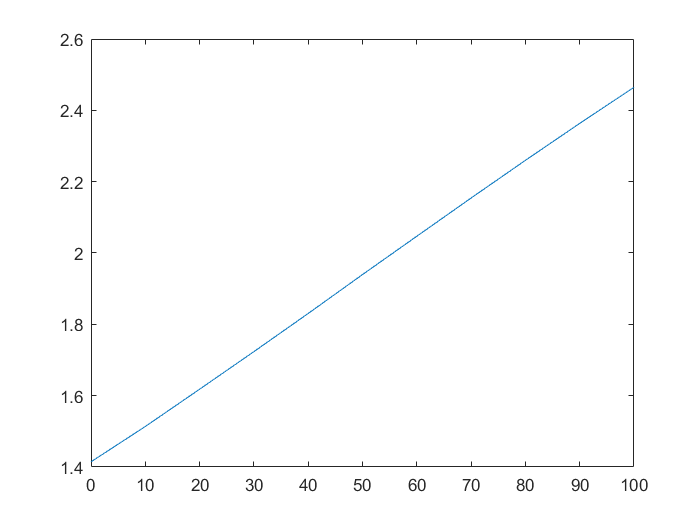

V= E*R_T(1,:)./(R_T(1,:)+R_lin);
plot(R_T(2,:),V)

R=sym("R",[1 3])

$$R = \left(\begin{array}{ccc} R_{1} & R_{2} & R_{3} \end{array}\right)$$

R1=R_lin;
Vo0 = V(1)*(R(3)*(R1+R(2))/(R1*R(2))+1)-E*R(3)/R1

$$Vo0 = \frac{3185260782192887\,R_{3}\,\left(R_{2}+\frac{6103425029801485}{2199023255552}\right)}{6249907230516720640\,R_{2}}-\frac{2199023255552\,R_{3}}{1220685005960297}+\frac{3185260782192887}{2251799813685248}$$

Vo10= V(11)*(R(3)*(R1+R(2))/(R1*R(2))+1)-E*R(3)/R1

$$Vo10 = \frac{5549774124806489\,R_{3}\,\left(R_{2}+\frac{6103425029801485}{2199023255552}\right)}{6249907230516720640\,R_{2}}-\frac{2199023255552\,R_{3}}{1220685005960297}+\frac{5549774124806489}{2251799813685248}$$

eqn1=Vo0_1 - 0

$$eqn1 = \frac{3185260782192887\,R_{3}\,\left(R_{2}+\frac{6103425029801485}{2199023255552}\right)}{6249907230516720640\,R_{2}}-\frac{2199023255552\,R_{3}}{1220685005960297}+\frac{3185260782192887}{2251799813685248}$$

eqn2 = Vo10 - 10

$$eqn2 = \frac{5549774124806489\,R_{3}\,\left(R_{2}+\frac{6103425029801485}{2199023255552}\right)}{6249907230516720640\,R_{2}}-\frac{2199023255552\,R_{3}}{1220685005960297}-\frac{16968224012045991}{2251799813685248}$$

R=solve([eqn1;eqn2])

R = struct with fields:
    R2: [1×1 sym]
    R3: [1×1 sym]


R3=double(R.R3)

R3 = 7.4779e+03

R2=double(R.R2)

R2 = 1.2829e+03

Vo=V.*(R3*(R1+R2)/(R1*R2)+1)-E*R3/R1

Vo =          0    0.9436    1.9388    2.9425    3.9616    5.0000    6.0233    7.0440    8.0501    9.0367   10.0000


Vo=double(Vo)

Vo =          0    0.9436    1.9388    2.9425    3.9616    5.0000    6.0233    7.0440    8.0501    9.0367   10.0000


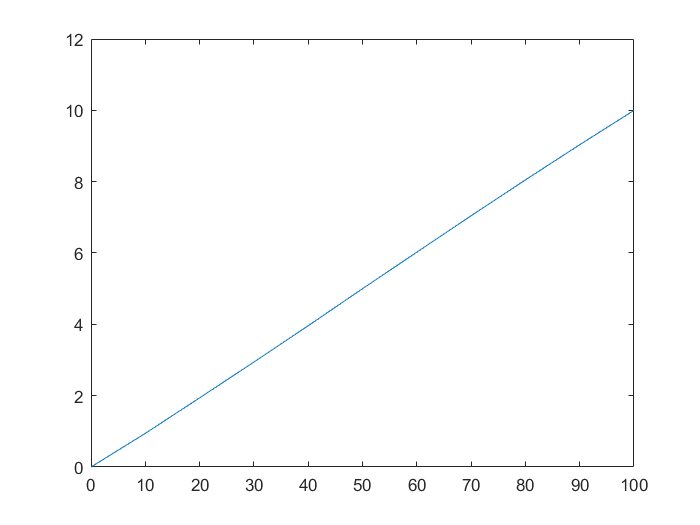

plot(R_T(2,:),Vo)

P=polyfit(Vo,R_T(2,:),1)

P =     9.9117    0.4950


T_est=Vo.*P(1)+P(2)

T_est =     0.4950    9.8477   19.7118   29.6604   39.7612   50.0536   60.1962   70.3134   80.2849   90.0638   99.6121


Res=T_est-R_T(2,:)

Res =     0.4950   -0.1523   -0.2882   -0.3396   -0.2388    0.0536    0.1962    0.3134    0.2849    0.0638   -0.3879


std=sqrt(norm(Res)/(length(Res)-1))*3

std = 0.9237

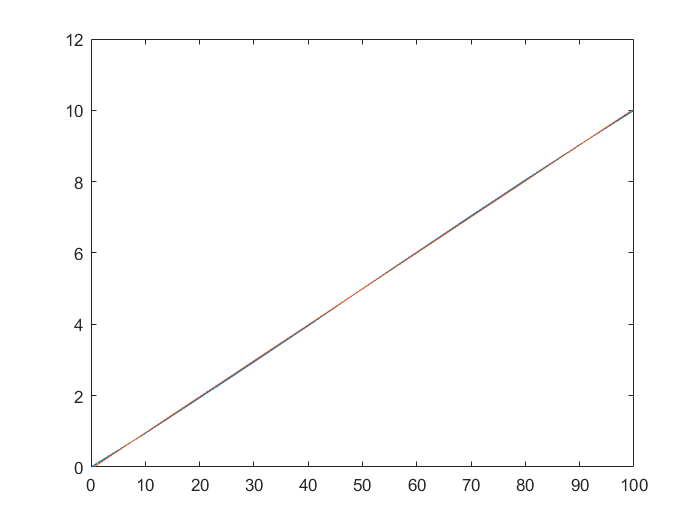

plot(R_T(2,:),Vo,T_est,Vo)

## Reale

Rlin=2763;
R1=2740;
R2=1297;
R3=7470;

syms Vt
Vo=-E/R1*R3+Vt*((R1+R2)/(R1*R2))*R3+Vt

$$Vo = \frac{2734073290760302969\,\mathrm{Vt}}{288230376151711744}-\frac{3735}{274}$$

Vt_= E*R_T(1,:)./(R_T(1,:)+R_lin)

Vt_ =     1.4145    1.5136    1.6181    1.7235    1.8305    1.9396    2.0470    2.1542    2.2598    2.3634    2.4646


q=double(subs(Vo,Vt,Vt_))

q =    -0.2135    0.7264    1.7177    2.7175    3.7325    4.7668    5.7861    6.8028    7.8048    8.7875    9.7471


m=double(subs(Vo,Vt,1))-q

m =    -3.9322   -4.8721   -5.8634   -6.8631   -7.8782   -8.9125   -9.9317  -10.9484  -11.9505  -12.9332  -13.8927


syms Rt 
eqn=Vt==E*Rt/(Rt+Rlin)

$$eqn = \mathrm{Vt}=\frac{5\,\mathrm{Rt}}{\mathrm{Rt}+2763}$$

Rt=solve(eqn,Rt)

$$Rt = -\frac{2763\,\mathrm{Vt}}{\mathrm{Vt}-5}$$

T_reale=[0.6 10.1 20.0 29.9 40.4 50.7 60.8 71.0 80.9 80.9 90.9 100.5]

T_reale =     0.6000   10.1000   20.0000   29.9000   40.4000   50.7000   60.8000   71.0000   80.9000   80.9000   90.9000  100.5000


# Relazione valori ideali

## Calcolo Rlin

R_T=[1095 1205 1328 1460 1603 1759 1924 2101 2289 2488 2698;
     0    10   20   30   40   50   60   70   80   90   100];
P_in=fit(R_T(2,:)',R_T(1,:)','poly1')

P_in =      Linear model Poly1:
     P_in(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =       16.03  (14.87, 17.19)
       p2 =        1012  (943.3, 1081)

R_est=R_T(2,:)*P_in.p1+P_in.p2;
err_lin_ini=max(abs(R_T(1,:)-R_est))/R_T(1,end)*100

err_lin_ini = 3.0713

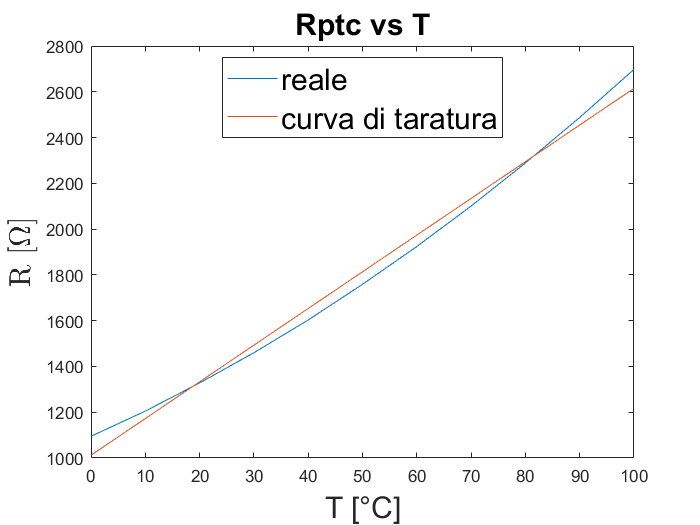

plot(R_T(2,:),R_T(1,:),R_T(2,:),R_est)
title("Rptc vs T","FontSize",18)
xlabel("T [°C]","FontSize",18)
ylabel("R [$\Omega$]","Interpreter","latex","FontSize",18)
legend("reale","curva di taratura","FontSize",18,'Location','best')


R_lin=sym("R_lin");
E=5;
V0= E*R_T(1,1)/(R_T(1,1)+R_lin);
V50= E*R_T(1,6)/(R_T(1,6)+R_lin);
V100= E*R_T(1,11)/(R_T(1,11)+R_lin);
eqn=V50-V0 == V100 - V50;
R_lin=solve(eqn);
R_lin=double(R_lin(2))

R_lin = 2.7755e+03

Vt= E*R_T(1,:)./(R_T(1,:)+R_lin);

P_Vt=fit(Vt',R_T(2,:)','poly1')

P_Vt =      Linear model Poly1:
     P_Vt(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =       94.39  (93.75, 95.04)
       p2 =        -133  (-134.3, -131.8)

T_est_BSFT=Vt*P_Vt.p1+P_Vt.p2;
err_lin_T_BSFT=max(abs(R_T(2,:)-T_est_BSFT))/R_T(2,end)*100

err_lin_T_BSFT = 0.4950

P_Vt=fit([Vt(1) Vt(end)]',[R_T(2,1) R_T(2,end)]','poly1')

P_Vt =      Linear model Poly1:
     P_Vt(x) = p1*x + p2
     Coefficients:
       p1 =       95.23
       p2 =      -134.7

T_est_EP=Vt*P_Vt.p1+P_Vt.p2;
err_lin_T_EP=max(abs(R_T(2,:)-T_est_EP))/R_T(2,end)*100

err_lin_T_EP = 0.6120

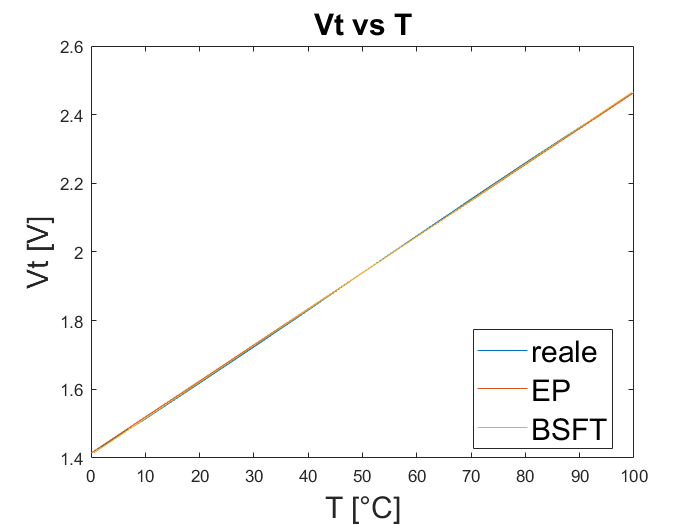

plot(R_T(2,:),Vt,T_est_EP,Vt,T_est_BSFT,Vt)
title("Vt vs T","FontSize",18)
xlabel("T [°C]","FontSize",18)
ylabel("Vt [V]","FontSize",18)
xlim([0 100])
legend("reale","EP","BSFT",'fontsize',18,'location','best')

## Calcolo R1 R2 R3

R=sym("R",[1 3]);
R1=R_lin

R1 = 2.7755e+03


Vo0 = Vt(1)*(R(3)*(R1+R(2))/(R1*R(2))+1)-E*R(3)/R1;
Vo10= Vt(11)*(R(3)*(R1+R(2))/(R1*R(2))+1)-E*R(3)/R1;
eqn1=Vo0 - 0;
eqn2 = Vo10 - 10;
R=solve([eqn1;eqn2]);
R3=double(R.R3)

R3 = 7.4779e+03

R2=double(R.R2)

R2 = 1.2829e+03

## Curva di taratura T vs Vout

Vo=Vt*(R3*(R1+R2)/(R1*R2)+1)-E*R3/R1

Vo =          0    0.9436    1.9388    2.9425    3.9616    5.0000    6.0233    7.0440    8.0501    9.0367   10.0000


[P_BSFT,G_BSFT]=fit(Vo',R_T(2,:)','poly1')

P_BSFT =      Linear model Poly1:
     P_BSFT(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =       9.912  (9.844, 9.979)
       p2 =       0.495  (0.09458, 0.8955)

G_BSFT = struct with fields:
           sse: 0.8989
       rsquare: 0.9999
           dfe: 9
    adjrsquare: 0.9999
          rmse: 0.3160


[P_EP,G_EP]=fit([Vo(1) Vo(end)]',[R_T(2,1) R_T(2,end)]','poly1')

P_EP =      Linear model Poly1:
     P_EP(x) = p1*x + p2
     Coefficients:
       p1 =          10
       p2 =          -0

G_EP = struct with fields:
           sse: 0
       rsquare: 1
           dfe: 0
    adjrsquare: NaN
          rmse: NaN


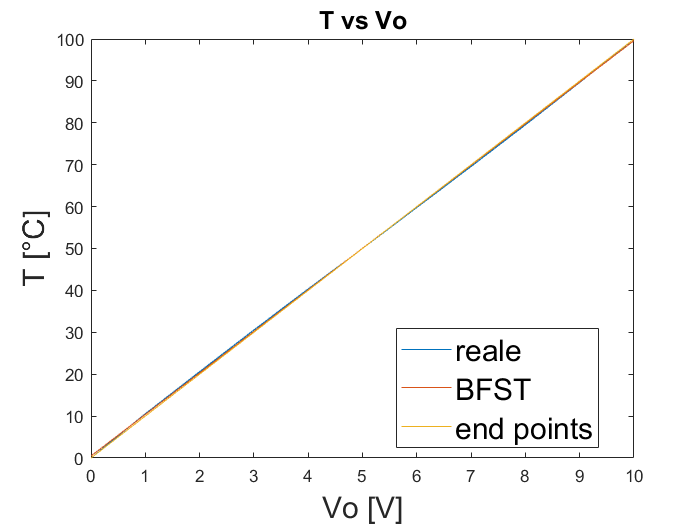

T_est_BFST=P_BSFT.p1*Vo+P_BSFT.p2;
T_est_EP=P_EP.p1*Vo+P_EP.p2;
plot(Vo,R_T(2,:),Vo,T_est_BFST,Vo,T_est_EP)
title("T vs Vo","FontSize",15)
xlim([0 10])
xlabel("Vo [V]","FontSize",18)
ylabel("T [°C]","FontSize",18)
legend("reale","BFST","end points","FontSize",18,'Location','best')

err_lin_EP_T=max(abs(R_T(2,:)-T_est_EP))/R_T(2,end)*100

err_lin_EP_T = 0.6120

err_lin_BFST_T=max(abs(R_T(2,:)-T_est_BFST))/R_T(2,end)*100

err_lin_BFST_T = 0.4950

# Relazione Valori reali

Rlin=2763;
R1=2740;
R2=1297;
R3=7470;

## Relazione Rt vs T

[P_BSFT,G_BSFT]=fit(R_T(2,:)',R_T(1,:)','poly1')

P_BSFT =      Linear model Poly1:
     P_BSFT(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =       16.03  (14.87, 17.19)
       p2 =        1012  (943.3, 1081)

G_BSFT = struct with fields:
           sse: 2.6155e+04
       rsquare: 0.9908
           dfe: 9
    adjrsquare: 0.9898
          rmse: 53.9080


R_est_BSFT=P_BSFT.p1*R_T(2,:)+P_BSFT.p2;
err_lin_BSFT=max(abs(R_T(1,:)-R_est_BSFT))/R_T(1,end)

err_lin_BSFT = 0.0307

[P_EP,G_EP]=fit([R_T(2,1) R_T(2,end)]',[R_T(1,1) R_T(1,end)]','poly1')

P_EP =      Linear model Poly1:
     P_EP(x) = p1*x + p2
     Coefficients:
       p1 =       16.03
       p2 =        1095

G_EP = struct with fields:
           sse: 0
       rsquare: 1
           dfe: 0
    adjrsquare: NaN
          rmse: NaN


R_est_EP=P_EP.p1*R_T(2,:)+P_EP.p2;
err_lin_EP=max(abs(R_T(1,:)-R_est_EP))/R_T(1,end)

err_lin_EP = 0.0510

## Relazione Vt vs T

V= double(E*R_T(1,:)./(R_T(1,:)+R_lin))

V =     1.4145    1.5136    1.6181    1.7235    1.8305    1.9396    2.0470    2.1542    2.2598    2.3634    2.4646


[P_BSFT_V,G_BSFT]=fit(R_T(2,:)',V','poly1')

P_BSFT_V =      Linear model Poly1:
     P_BSFT_V(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =     0.01059  (0.01052, 0.01067)
       p2 =       1.409  (1.405, 1.414)

G_BSFT = struct with fields:
           sse: 1.0088e-04
       rsquare: 0.9999
           dfe: 9
    adjrsquare: 0.9999
          rmse: 0.0033


V_est_BSFT=P_BSFT_V.p1*R_T(2,:)+P_BSFT_V.p2;
err_lin_BSFT_V=max(abs(V-V_est_BSFT))/V(end)

err_lin_BSFT_V = 0.0021

[P_EP_V,G_EP]=fit([R_T(2,1) R_T(2,end)]',[V(1) V(end)]','poly1')

P_EP_V =      Linear model Poly1:
     P_EP_V(x) = p1*x + p2
     Coefficients:
       p1 =      0.0105
       p2 =       1.415

G_EP = struct with fields:
           sse: 0
       rsquare: 1
           dfe: 0
    adjrsquare: NaN
          rmse: NaN


V_est_EP=P_EP_V.p1*R_T(2,:)+P_EP_V.p2;
err_lin_EP_V=max(abs(V-V_est_EP))/V(end)

err_lin_EP_V = 0.0026

## Relazione Vout vs Rt

Vo=V.*(R3*(R1+R2)/(R1*R2)+1)-E*R3/R1

Vo =    -0.2135    0.7264    1.7177    2.7175    3.7325    4.7668    5.7861    6.8028    7.8048    8.7875    9.7471


[P_BSFT_V,G_BSFT]=fit(R_T(2,:)',Vo','poly1')

P_BSFT_V =      Linear model Poly1:
     P_BSFT_V(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =      0.1005  (0.0998, 0.1012)
       p2 =     -0.2628  (-0.3033, -0.2223)

G_BSFT = struct with fields:
           sse: 0.0091
       rsquare: 0.9999
           dfe: 9
    adjrsquare: 0.9999
          rmse: 0.0318


## Vout vs T

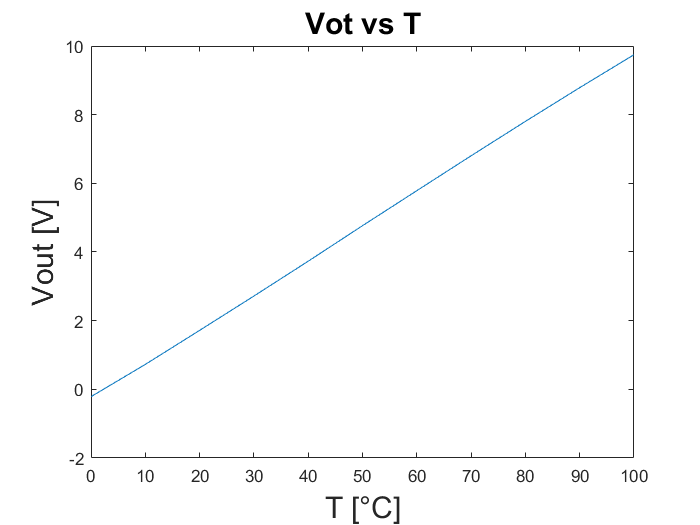

plot(R_T(2,:),Vo)
title("Vot vs T","FontSize",18)
xlabel("T [°C]","FontSize",18)
ylabel("Vout [V]","FontSize",18)

[P_BSFT,G_BSFT]=fit(Vo',R_T(2,:)','poly1')

P_BSFT =      Linear model Poly1:
     P_BSFT(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =       9.951  (9.883, 10.02)
       p2 =       2.619  (2.231, 3.007)

G_BSFT = struct with fields:
           sse: 0.8989
       rsquare: 0.9999
           dfe: 9
    adjrsquare: 0.9999
          rmse: 0.3160


[P_EP,G_EP]=fit([Vo(1) Vo(end)]',[R_T(2,1) R_T(2,end)]','poly1')

P_EP =      Linear model Poly1:
     P_EP(x) = p1*x + p2
     Coefficients:
       p1 =       10.04
       p2 =       2.143

G_EP = struct with fields:
           sse: 8.6538e-28
       rsquare: 1
           dfe: 0
    adjrsquare: NaN
          rmse: NaN


T_est_BFST=P_BSFT.p1*Vo+P_BSFT.p2;
T_est_EP=P_EP.p1*Vo+P_EP.p2;
err_lin_EP_T=max(abs(R_T(2,:)-T_est_EP))/R_T(2,end)*100

err_lin_EP_T = 0.6120

err_lin_BFST_T=max(abs(R_T(2,:)-T_est_BFST))/R_T(2,end)*100

err_lin_BFST_T = 0.4950

T_reale=[0.6 10.1 20.0 29.9 40.4 50.7 60.8 71.0 80.9 90.9 100.5]

T_reale =     0.6000   10.1000   20.0000   29.9000   40.4000   50.7000   60.8000   71.0000   80.9000   90.9000  100.5000


err_max=max(abs(R_T(2,:)-T_reale))

err_max = 1